**1**. Implementieren Sie ein MATLAB-Skript, das für ein gegebenes Eingangsbild sämtliche Schritte der Hough-Transformation visualisiert, d.h. insbesondere das binäre **Kantenbild**, den **Hough-Raum**, und die in das Originalbild projizierten **Geradensegmente**. Falls nötig, finden Sie in der MATLAB Hilfe ein Code-Beispiel, auf dem Sie aufbauen können.

MATLAB bietet Funktionen zur Durchführung einer Hough-Transformation für gerade Linienelemente. Diese Funktionen sind:

`[H, theta, rho] = hough(BW) - `Berechnet die Hough-Transformierte aus einem Binärbild.

`peaks = houghpeaks(H, numpeaks) - `Sucht Höchstwerte im Hough-Raum

`lines = houghlines(BW, theta, rho, peaks) - `Bildet mit Hilfe der gefundenen Geraden und des Binärbilds zugehörige Geradensegmente

binäres Kantenbild:

%simulationsparameter
%bild=



D=0

D = 0

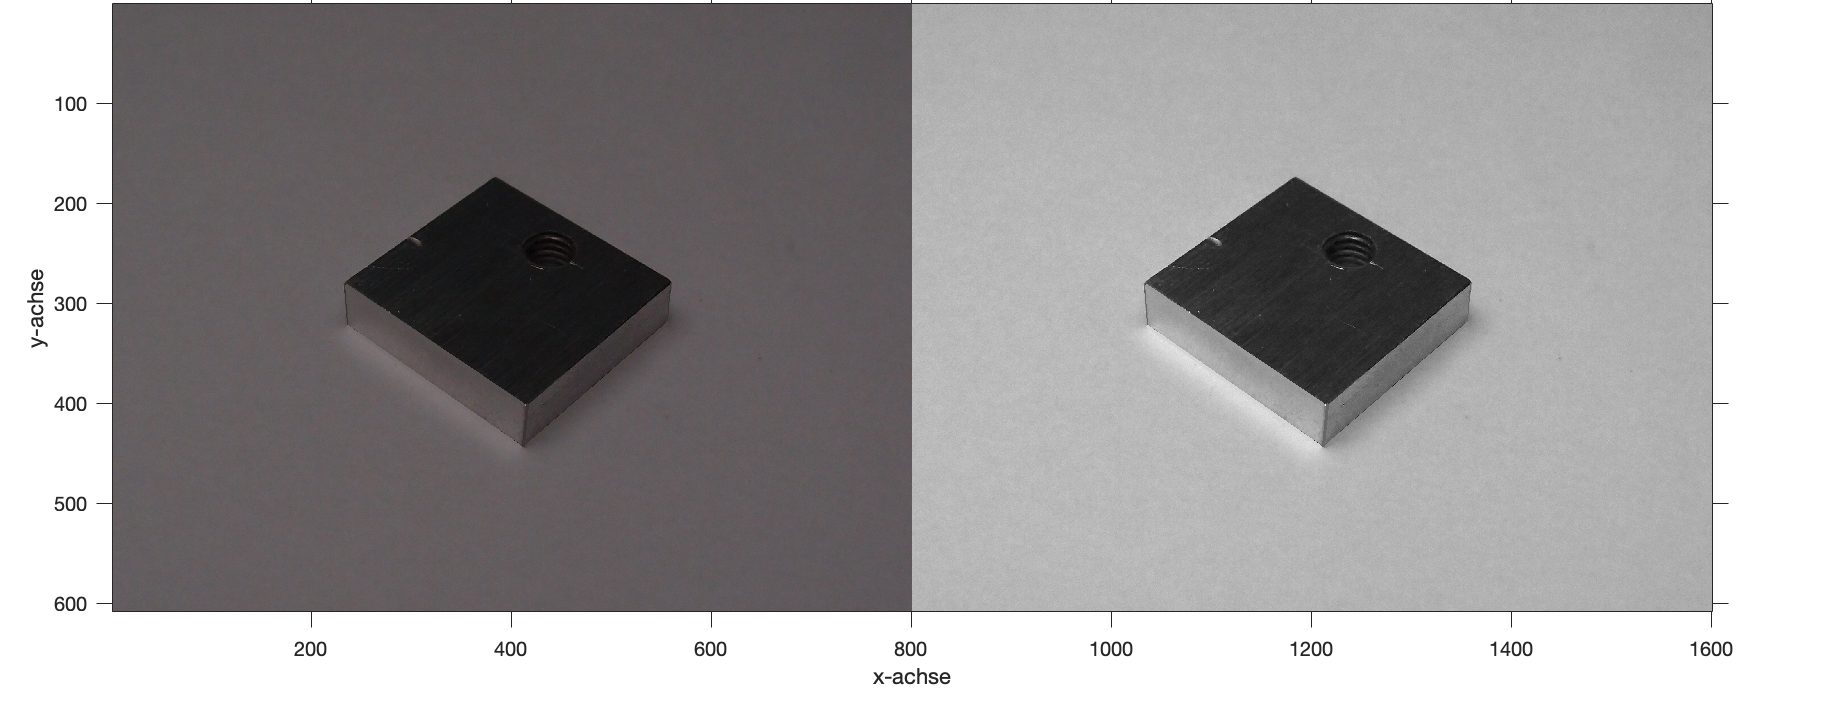

%Image Einlesen
A{1,1}=imrotate(imread("/Users/tonystark/Desktop/TUB 2. Semester/BGA/Bilder-20210125/Platte2.png"),D,"crop");
A{2,1}=rgb2gray(A{1,1});
A{3,1}=imbinarize(A{1,1},"global");
figure(1)
imshowpair(A{1,1},A{2,1},"montage");
title("Graustufenübersatzung","FontSize",20)
xlabel("x-achse");ylabel("y-achse");
axis on, axis normal;

%edge detector
A{4,1}=edge(A{1,1},"Canny");

Error using edge
Expected input number 1, I, to be two-dimensional.

Error in edge>parse_inputs (line 482)
validateattributes(I,{'numeric','logical'},{'real','nonsparse','2d'},mfilename,'I',1);

Error in edge (line 213)
[a,method,thresh,sigma,thinning,H,kx,ky] = parse_inputs(args{:});

inshow(A{3,1});




Hough-Raum:

[H,theta,rho]=hough()

in das Originalbild projizierte Geradensegmente:

Testen Sie die grundlegende Funktionsweise Ihres Programms anhand der Bilderserie „Test_Bild....png“. Versuchen Sie dabei die einzelnen Teilergebnisse und deren Zustandekommen nachzuvollziehen.

Recherchieren Sie die Funktionsweise der nachfolgend aufgelisteten Parameter und untersuchen Sie deren Einfluss auf das Ergebnis:

a.    Eigenschaften des Canny-Filters

b.    Auflösung von rho und theta

c.    Anzahl und Schwellwert der zu findenden Maximalwerte im Hough-Raum

d.    Größe der Nachbarschaft, in der weitere Extremwerte unterdrückt werden

e     Die Mindestlänge und maximale Lückengröße zur Bildung der Geradensegmente

Diskutieren Sie den Effekt der einzelnen Parameter! 

**2**. Versuchen Sie nun, sämtliche Kanten im Bild „Platte1.png“ als Geradensegmente zu erkennen. Welche Segmente bereiten besondere Schwierigkeiten? Warum?

binäres Kantenbild:

Hough-Raum:

in das Originalbild projizierte Geradensegmente:

**Bonus:**

Wenden Sie Ihr in Aufgabe 2 angepasstes Skript zunächst ohne weitere Veränderungen auf das Bild „Platte2.png“ an. Diskutieren Sie das Ergebnis und schlagen Sie möglichst begründet Parameteränderungen vor, mit denen erneut sämtliche Geradensegmente hervorgehoben werden können.